# Time evolution for the NLS equation on a dumbbell graph

Evolves the cubic nonlinear Schrodinger equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

tag='dumbbell';
Phi = quantumGraphFromTemplate(tag,'discretization','Chebyshev','nX',32);

## Define the function

Defining the non-linear Schrodinger equation on Phi.

A = Phi.laplacianMatrix;
B = Phi.weightMatrix;

f =@(t,z) -1i*( A*z + (2*(B*z).^2.*conj(B*z)));

## Time evolution

The first step for our time evolution is developing a good initial condition. We will use a solution to the stationary problem.

First, we must generate solutions to the stationary problem.

nToPlot=4;
nDoubles=1;
nTriples=0;
diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

Saved to directory data\dumbbell\018.
Run number is 18.



options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
eigNumber=1;
[bn1,bl1]=continueFromEig(tag,diagramNumber,eigNumber,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\018\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.



Lambda0=-4;
edges=[1 2];
signs=[1 1];
filenumber=saveHighFrequencyStandingWave(tag,diagramNumber,Lambda0,edges,signs);

File saved to data\dumbbell\018\savedFunction.001.
File number is 1. 



options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
[bn2,bl2]=continueFromSaved(tag,diagramNumber,filenumber,-1,options);

N threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\018\branch002.
No branching bifurcations found.


Then, load the solution in and use it as an initial condition.

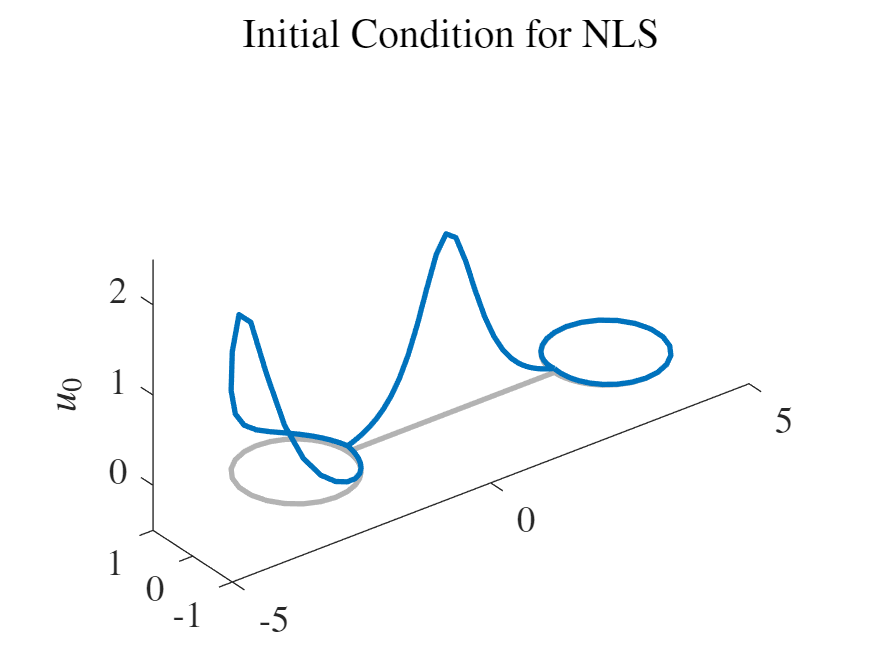

efunc = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'PhiColumn.001'));
u0 = efunc;
Phi.plot(u0)
title('Initial Condition for NLS')
zlabel('$u_0$')

In addition to the initial condition, we need the step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used a modified version of the DoPri-8 scheme.

tend = 1;
deltat = 1e-02;
% [u,t] = Phi.timeEvolveDAE(f,u0,deltat,tend,4);
[t,u] = Phi.timeEvolveDH(f,u0,tend);

## Plotting the solution

As expected, our solution remains stationary.

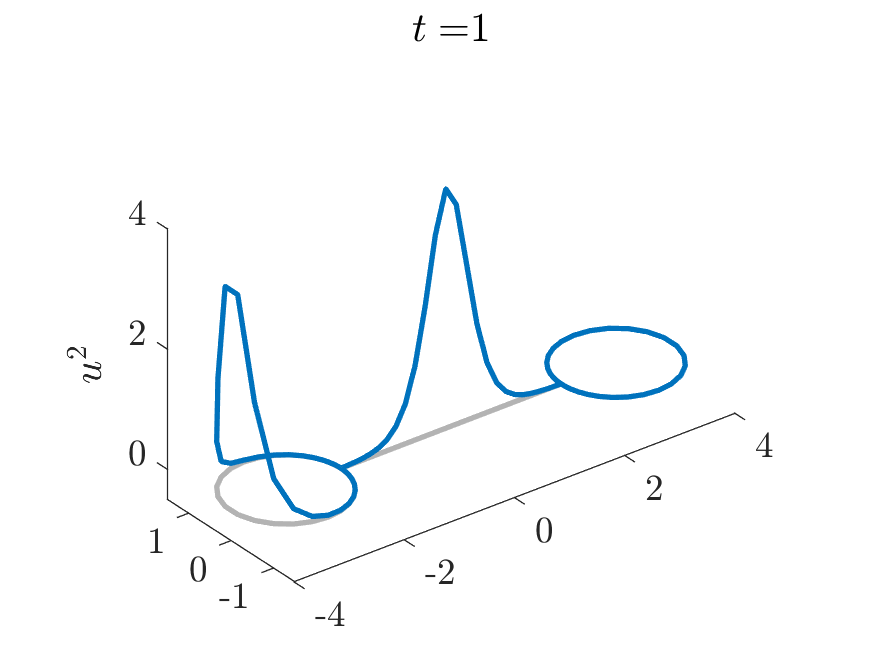

n = size(u,2);
scale = floor(n/100);
for i=1:floor(n/scale)
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-4 4 -1.5 1.5 -.5 4])
    daspect([1 1 1])
    title(['$t=$',num2str(round(t(scale*i),2))])
    zlabel('$u^2$')
    pause(.0000000001)
end

## Error analysis

Check for conservation of energy and mass.

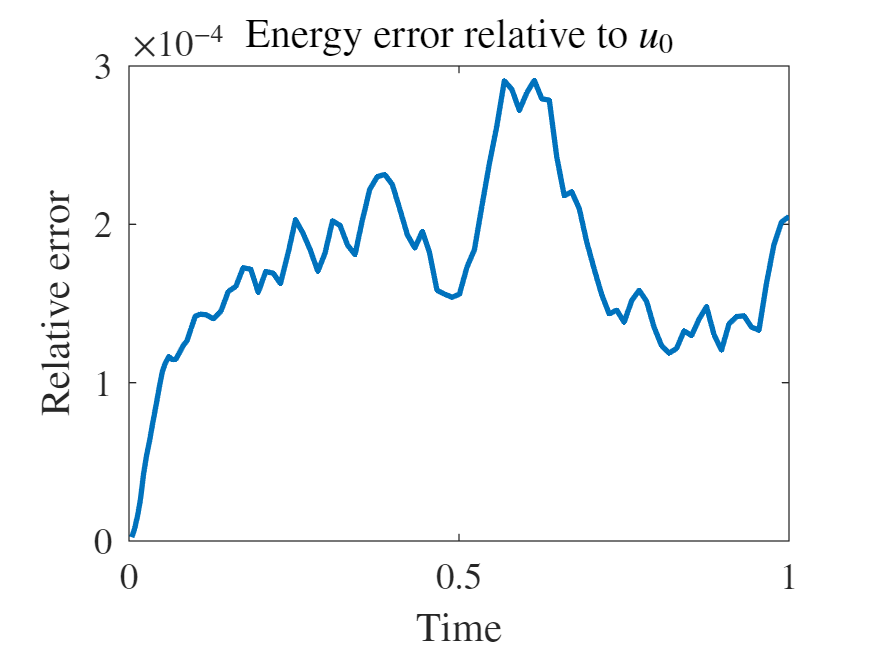

energyDiff = zeros(floor(n/scale),1);
massDiff = zeros(floor(n/scale),1);
tplot = zeros(floor(n/scale),1);
u0energy = 0.5*( Phi.dot( A*u(:,1) , conj(u(:,1)) ) + Phi.dot( u(:,1).^2 , conj(u(:,1).^2) ));
u0mass = Phi.dot(u(:,1),conj(u(:,1)));

for i=1:floor(n/scale)
    ui = u(:,scale*i);
    energyDiff(i) = abs( (0.5*(Phi.dot(A*ui,conj(ui)) + Phi.dot(ui.^2,conj(ui.^2))) - u0energy) / u0energy );
    massDiff(i) = abs( (Phi.dot(ui,conj(ui)) - u0mass) / u0mass );
    tplot(i) = t(scale*i);
end

disp('')
figure
plot(tplot,energyDiff)
title('Energy error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')

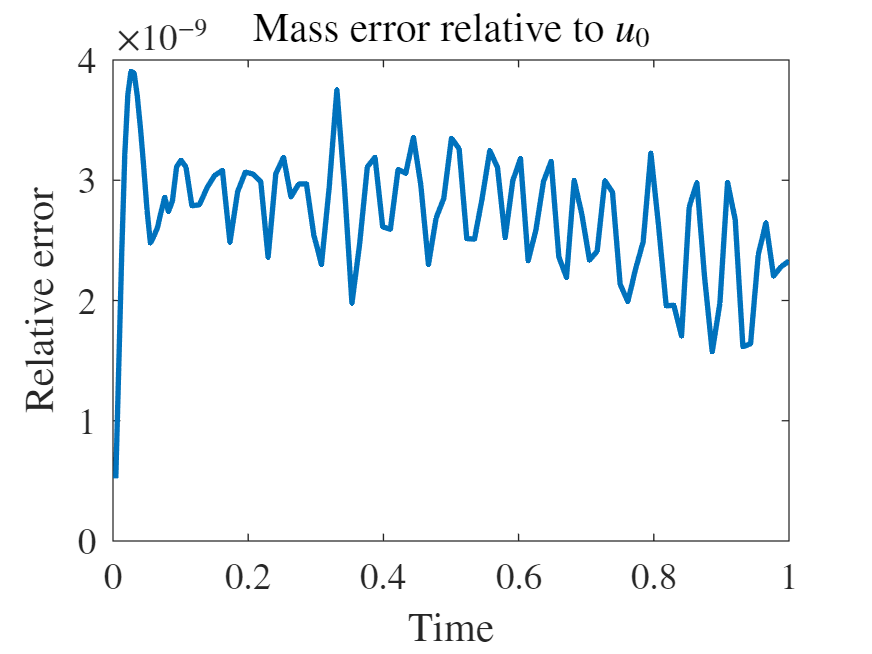


figure
plot(tplot,massDiff)
title('Mass error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')